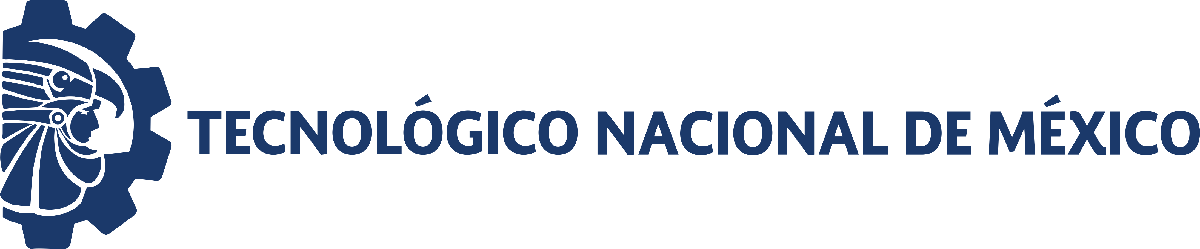                                 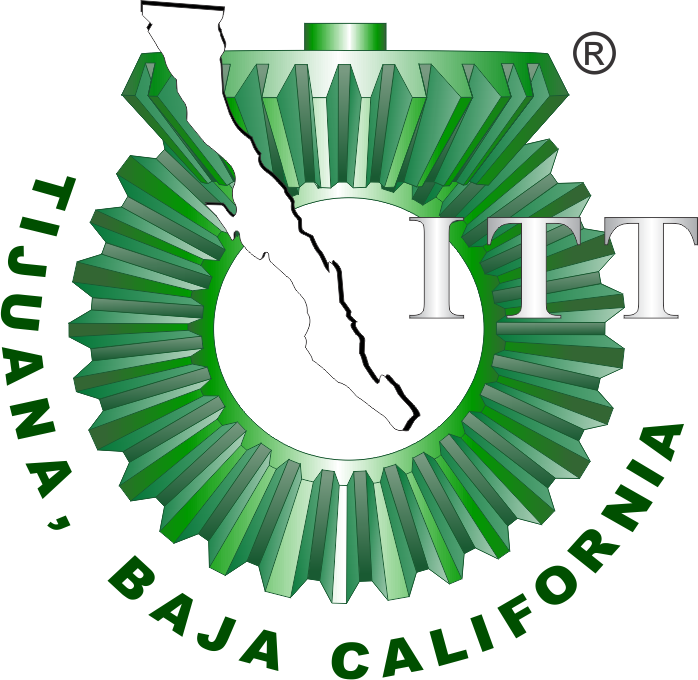

# Práctica tres: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

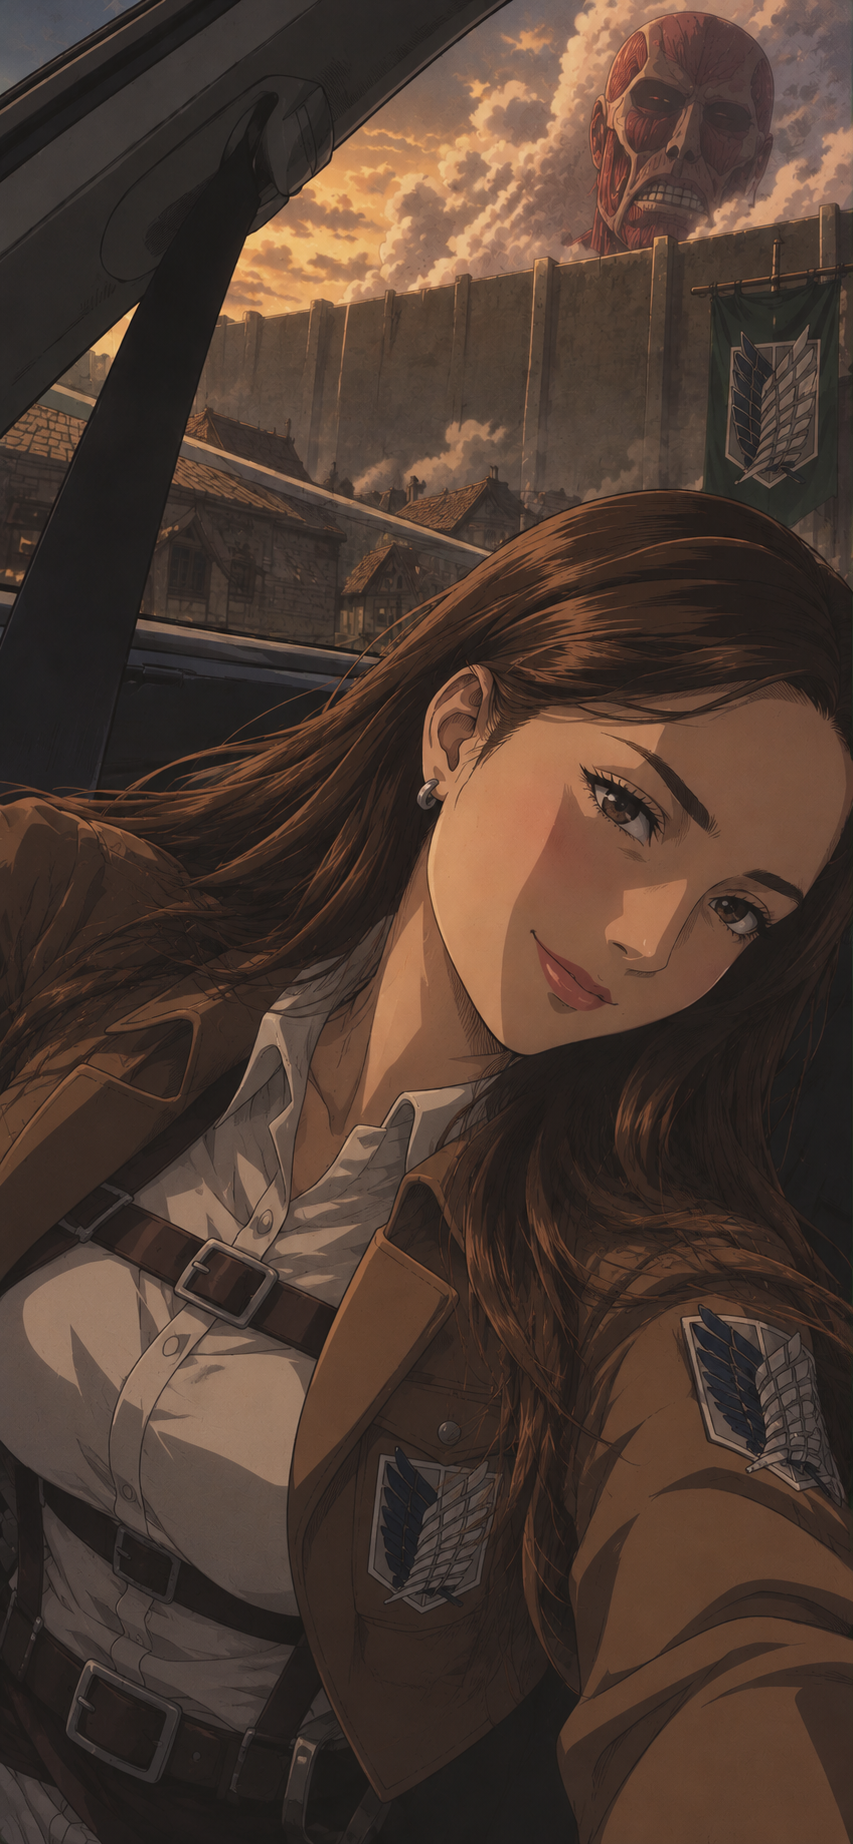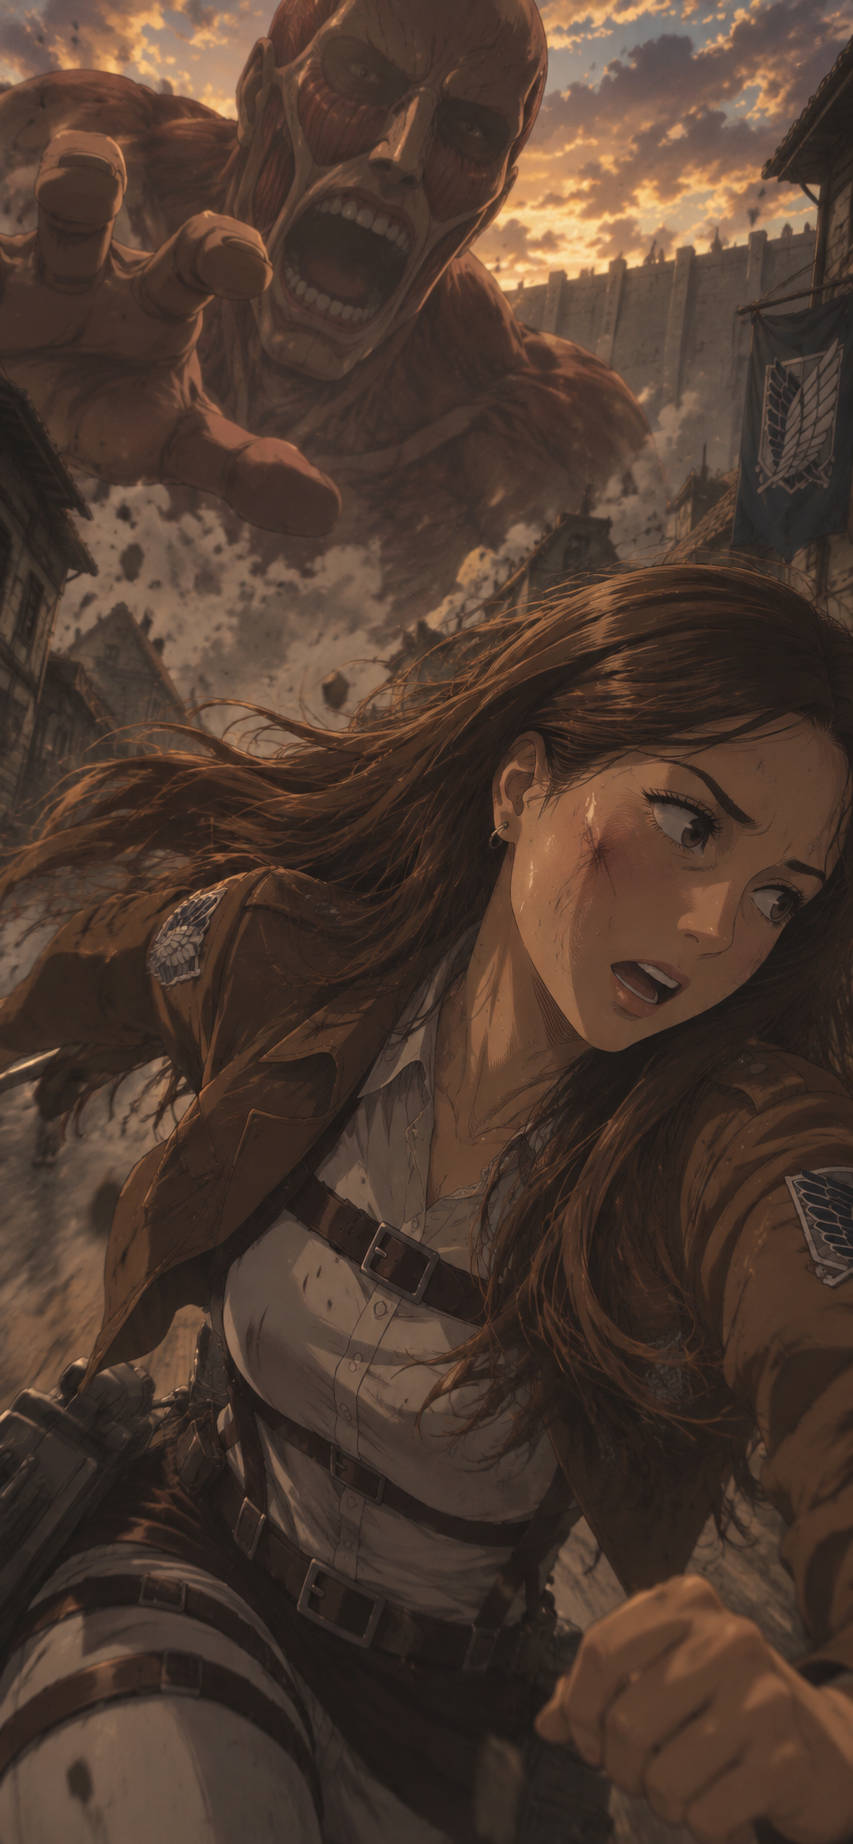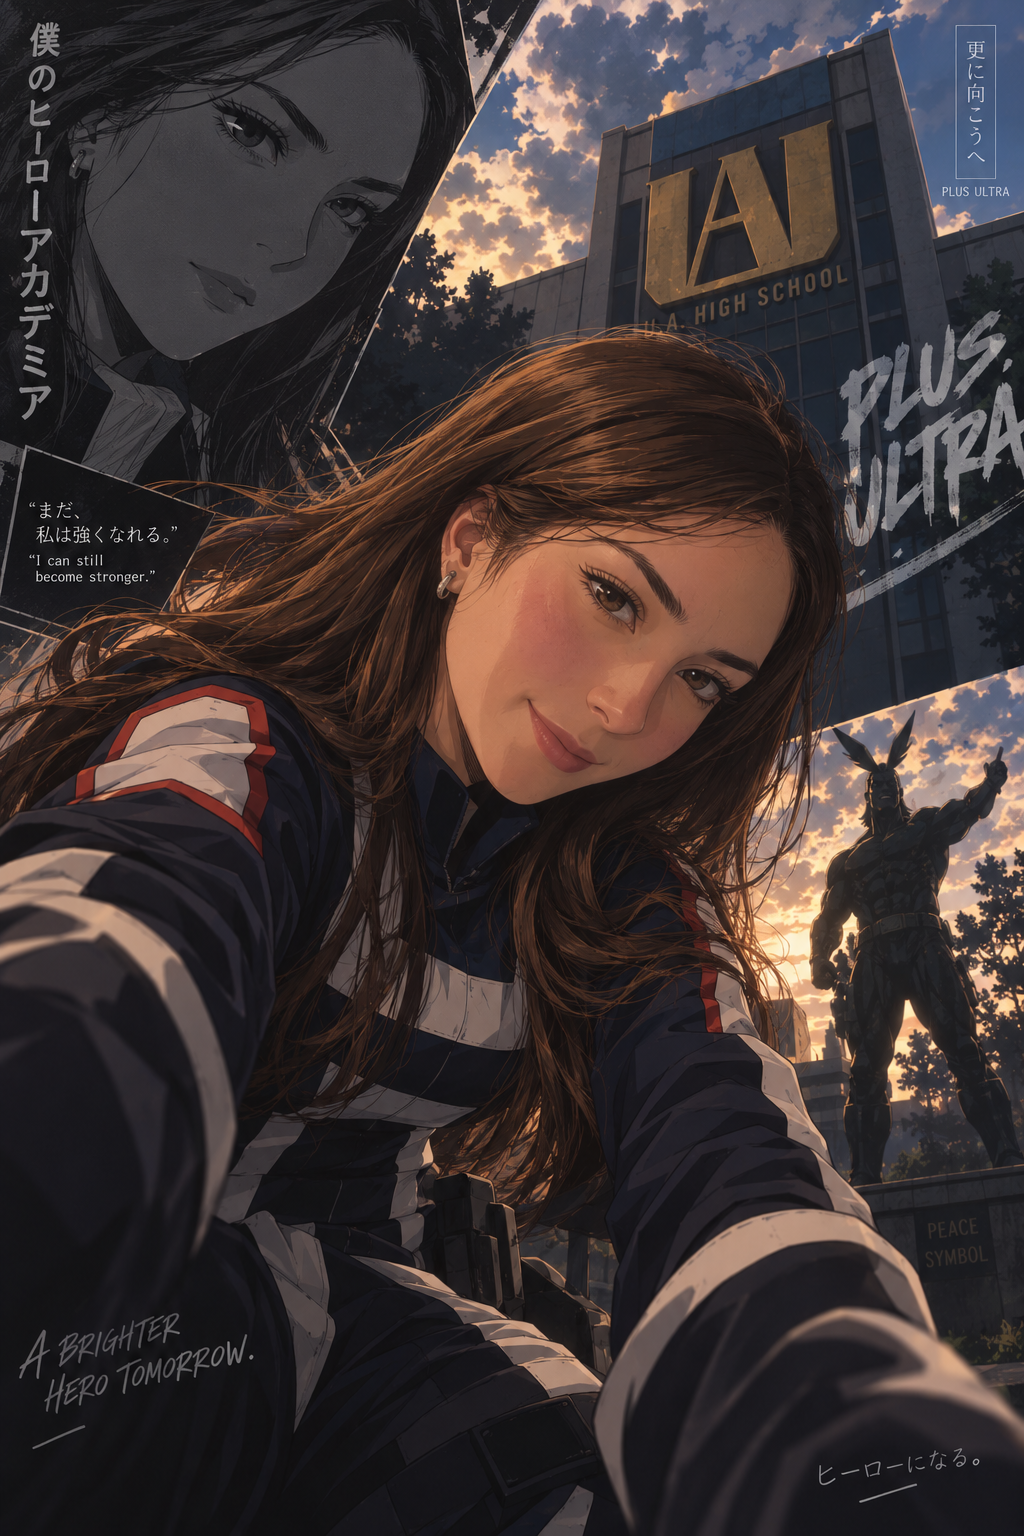

Nombre del alumno: Muñoz Meneses María Luisa

Número de control: 23210714

Correo institucional: l23210714@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema.slx')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';


## Respuesta Impulso unitario 

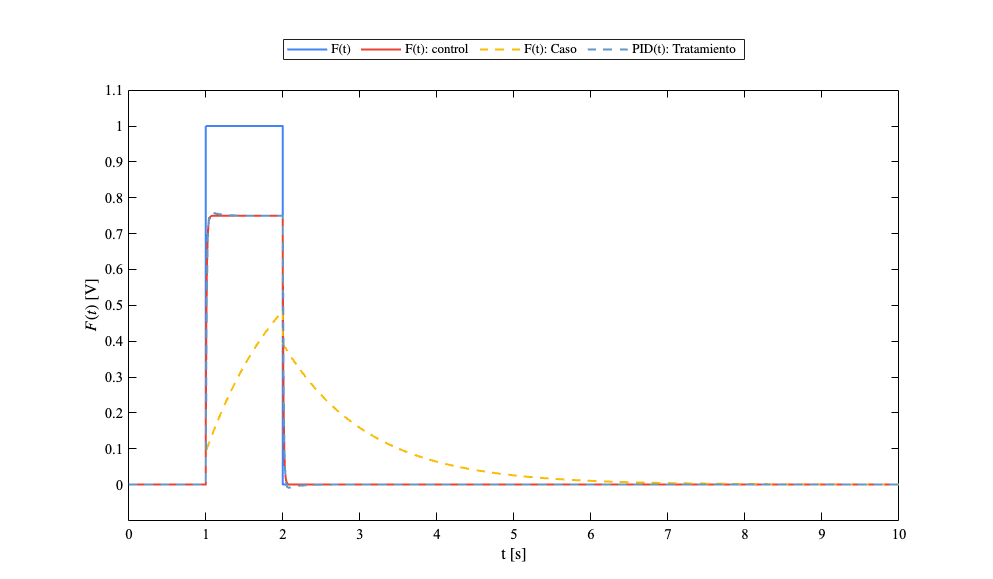

x = sim('sistema',parameters);
plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID, 'impulso unitario')

## Modelo de EDOs

dt = 1e-3;
t = (0:dt:10)';
F = zeros(length(t),1); F(1/dt : 2/dt) = 1;
PID = interp1(x.t, x.PID, t, 'previous');
par_control = [0.25,10e-6,100e-6,100];
par_caso    = [0.25,10e-6,100e-6,10e3];

Fs_control = musculoesqueletico(par_control,F,t);
Fs_caso    = musculoesqueletico(par_caso,F,t);

plotsignals(t,F,Fs_control,Fs_caso,PID,'EDOsys')

function Fs = musculoesqueletico(par,F,t)
alpha = par(1); Cs = par(2); Cp = par(3); R = par(4);
dt = t(2)-t(1);
n = length(t)-1;
x = zeros(length(t),1);
Fs = zeros(length(t),1);
for i = 1:n
    x(i+1)  = x(i) + ((F(i)-x(i))/(R*(Cp+Cs)))*dt;
    Fs(i+1) = Cs*F(i)/(Cp+Cs) + (1 - alpha - Cs/(Cp+Cs))*x(i);
end
end

## **Funcion: Respuestas de la simulacion **

function plotsignals(t,F,Fsx,Fsy,PID,signal)
set(figure(),'color','w')
set(gcf,'units','inches','position', [0.5,0.5,12,7])
set(gca, 'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
clr1 = [66, 133, 244]/255;
clr2 = [234, 67, 53]/255;
clr3 = [251, 188, 5]/255;
clr4 = [100,150,200]/255;
order = [clr1; clr2; clr3;clr4]; colororder(order)
xlabel('t [s]','Interpreter','latex')
ylabel('$F(t)$ [V]', 'Interpreter','latex')
xlim([0 10]); xticks(0:1:10)
ylim([-0.1 1.1]); yticks(0:0.1:1.1)
if signal == "impulso unitario"
    plot(t,F,'-',t,Fsx,'-',t,Fsy,'--',t,PID,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    L = legend('F(t)','F(t): control','F(t): Caso','PID(t): Tratamiento');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')


end
set(gcf,'Color','white')
set(gca,'Color','white','XColor','black','YColor','black')
set(L,'Color','white','TextColor','black')
exportgraphics(gcf,'Sistemamusculoesqueletico.pdf', 'ContentType','vector')

end





Respuesta de simulacion
function plotsignals(t,x1,x2,x3,x4,signal)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,10,5])
set(gca,'fontname','times new roman','fontsize',12)
hold on; grid off; box on;
clr1 = [0,114,189]/255;
clr2 = [237,177,32]/255;
clr3 = [34,139,34]/255;
clr4 = [0.5, 0.5, 0.5]/255;
order = [clr1;clr2;clr3;clr4]; colororder(order)

plot(t,x1,'-','LineWidth',0.25,'Color',clr1)
plot(t,x2,'--','LineWidth',0.25,'Color',clr2)
plot(t,x3,'--','LineWidth',0.25,'Color',clr3)
plot(t,x4,':','LineWidth',1,'Color',clr4)
L = legend('$F(t)$','$F_s(t):Control$','$F_s(t):Caso$','$PID(t):Tratamiento$');

set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')
xlabel('$t$ [s]','interpreter','latex')
ylabel('$F(t)$ [V]','interpreter','latex')
xlim([0 10]); xticks(0:1:10)
ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
exportgraphics(gcf,[signal,'matlab.pdf'],'ContentType','vector')
end